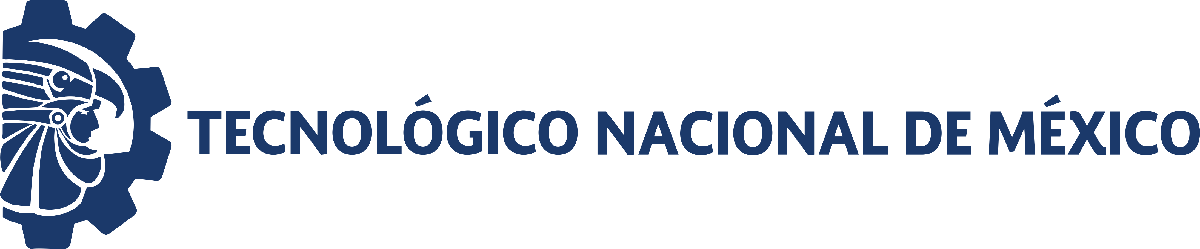                                 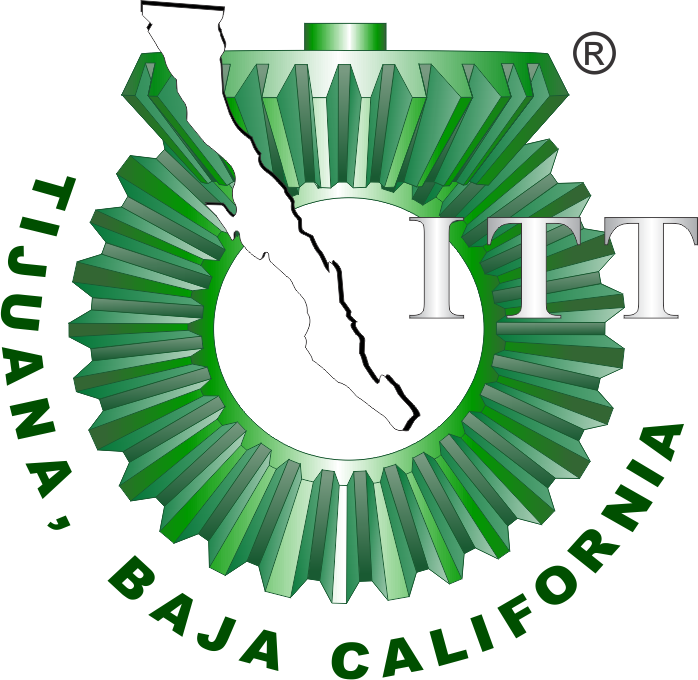

# Práctica 3: Modelado y control del sistema musculoesquelético

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

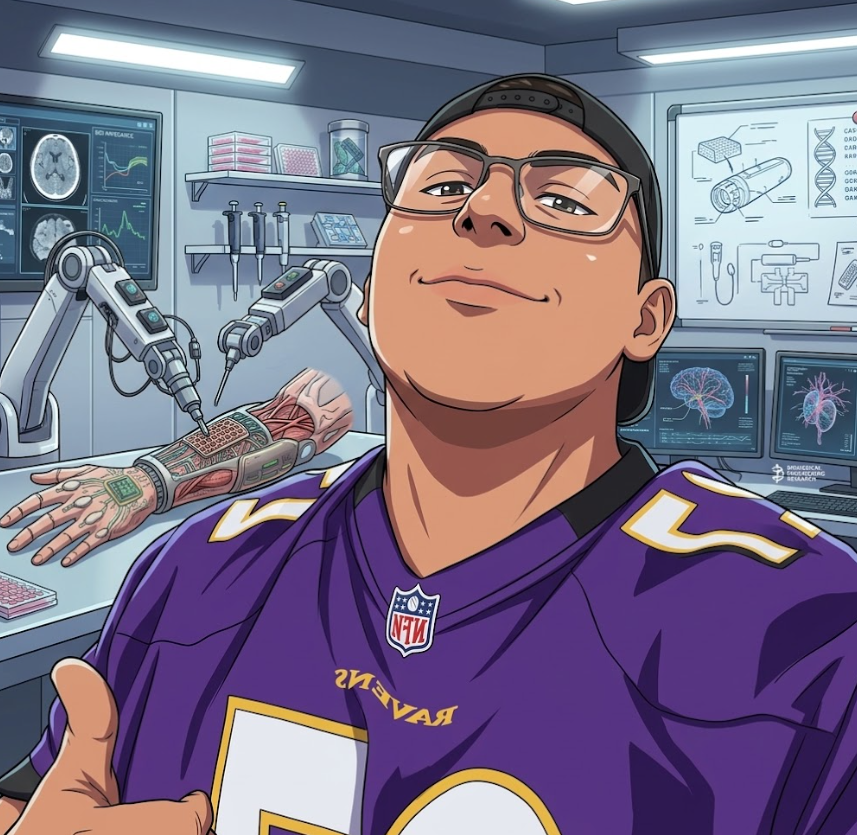

Nombre del alumno: Zaid Alexander Arredondo Medina

Número de control: 23212180

Correo institucional: L23212180**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Sistema3';
open_system(file)
parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';

## Respuesta en lazo abierto

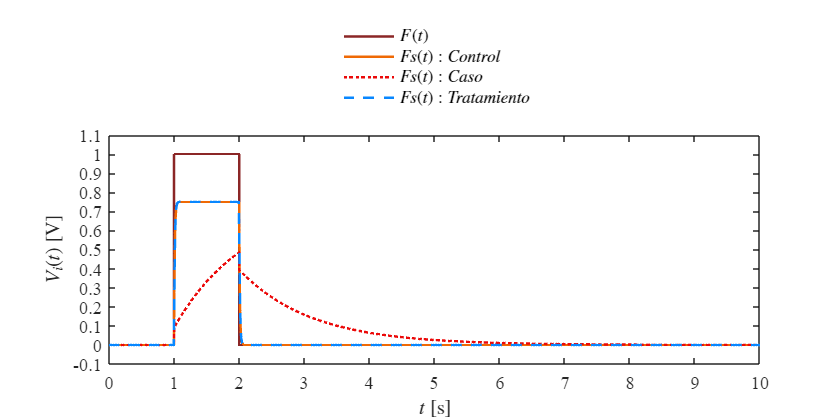


x=sim(file,parameters);
signal = 'Individual';
plotSignals(x.t,x.F,x.Fsx,x.Fsy,x.PID,signal)

## **FUNCION: Respuesta de la simulacion**

function plotSignals(t,F,Fsx,Fsy,PID,signal)
    set(figure(),'color','white')
    set(gcf,'units','inches','position',[1,1,7,3.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;

    clr1=[139, 38, 38]/255;
    clr2=[239, 105, 5]/255;
    clr3=[235, 9, 9]/255;
    clr4=[8, 135, 255]/255;
    order=[clr1;clr2;clr3;clr4]; colororder(order)
    
   

    if signal=="Individual"
        plot(t,F,'-',t,Fsx,'-',t,Fsy,':',t,PID,'--','LineWidth',1.5,'MarkerSize',2.5,'MarkerIndices',...
            1:1e3:length(t));
        L = legend('$F(t)$','$Fs(t): Control$','$Fs(t): Caso$','$Fs(t): Tratamiento$');
        set(L,'interpreter','latex','location','northoutside','orientation','vertical','Box','off')
        
        xlabel('$t$ [s]','interpreter','latex')
        ylabel('$V_i(t)$ [V]','interpreter','latex')
        xlim([0 10]); xticks(0:1:10)
        ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)
    
    end

    exportgraphics(gcf,[signal,'_matlab.pdf'],'ContentType','vector')



end